# Contrast maps for stimulus experience

Model (CESO)

- parameter:

-     **C**ue onset, 

-     **E**xpectationRating onset 

-     **S**timulus onset

-     **O**utcomeRating onset

- Motion covariate: 24DOF + CSF

- Spike combined into one regressor (Incorrect)

## Pain > (Vicarious & Cognitive)

#### Pain > VC :: load dataset

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_CESO/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0005.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii


sampleto = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_CESO/1stLevel/sub-0013/con_0005.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 39535452 bytes
Loading image number:    99
Elapsed time is 18.734762 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 9416678  Bit rate: 23.17 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C'};

#### Pain > VC :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

SPM12: spm_check_registration (v7759)              16:44:46 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


#### Pain > VC :: Plot diagnostics, before l2norm

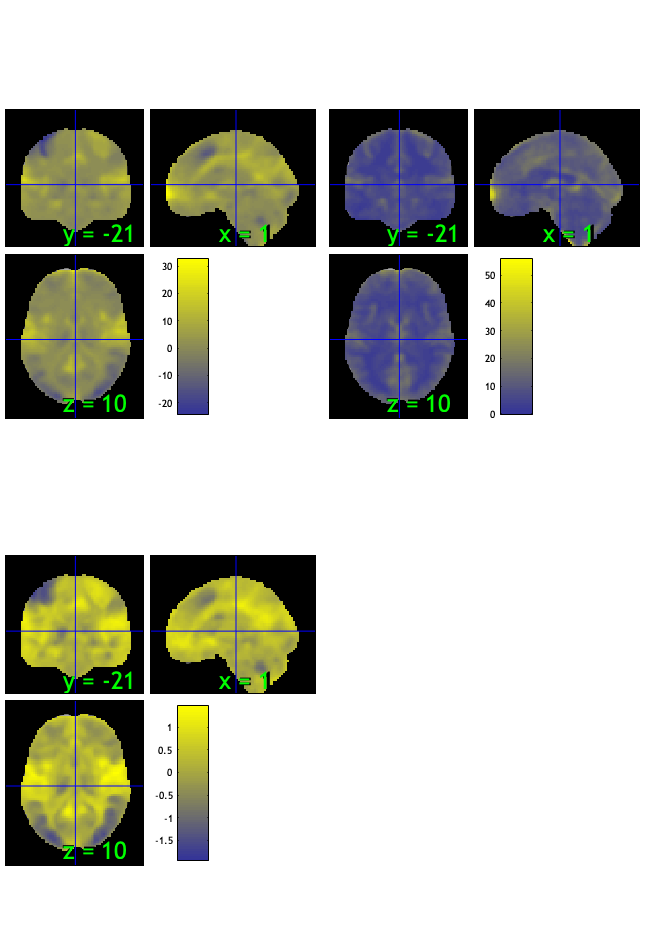

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 20.20%
Expected 4.95 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 3 images		Cases 26 27 75 
Uncorrected: 6 images		Cases 6 26 27 35 75 99 

Retained 6 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 41.41%
Expected 4.95 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 7 images		Cases 6 13 26 35 65 70 75 

Mahalanobis (cov and corr, q<0.05 corrected):
  3 images 
                               Outlier_count    Percentage
                   

SPM12: spm_check_registration (v7759)              16:45:23 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

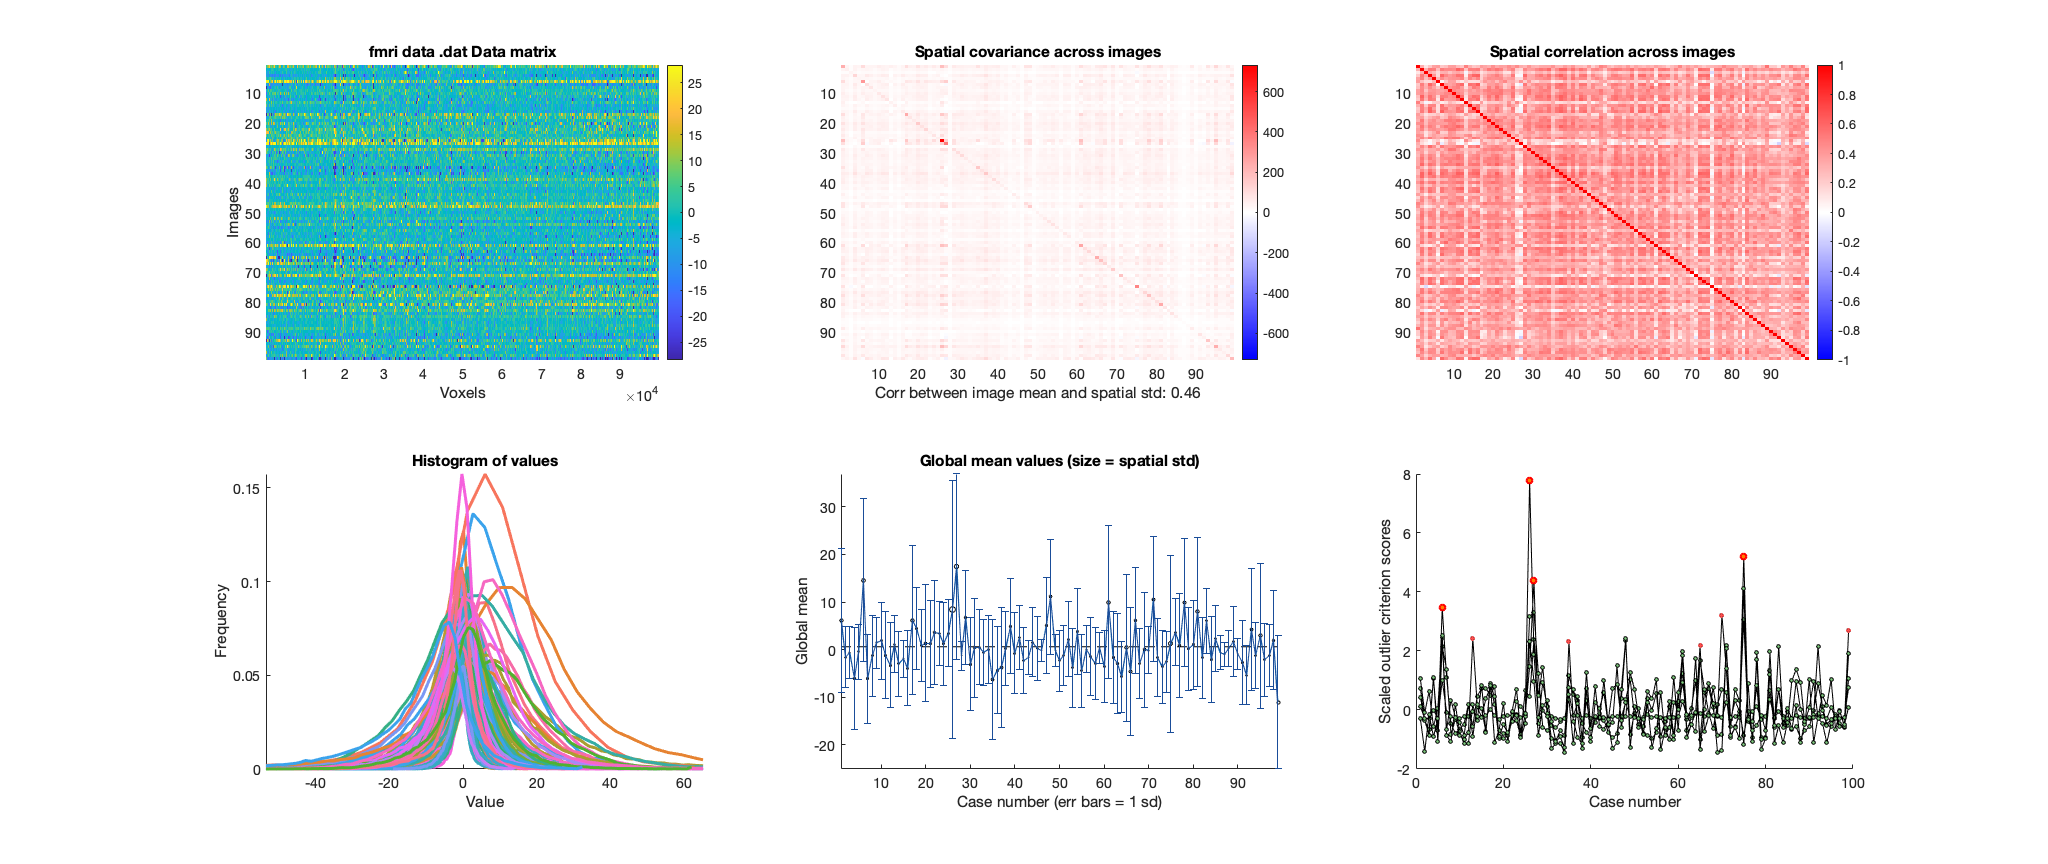

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Pain > VC :: run robfit

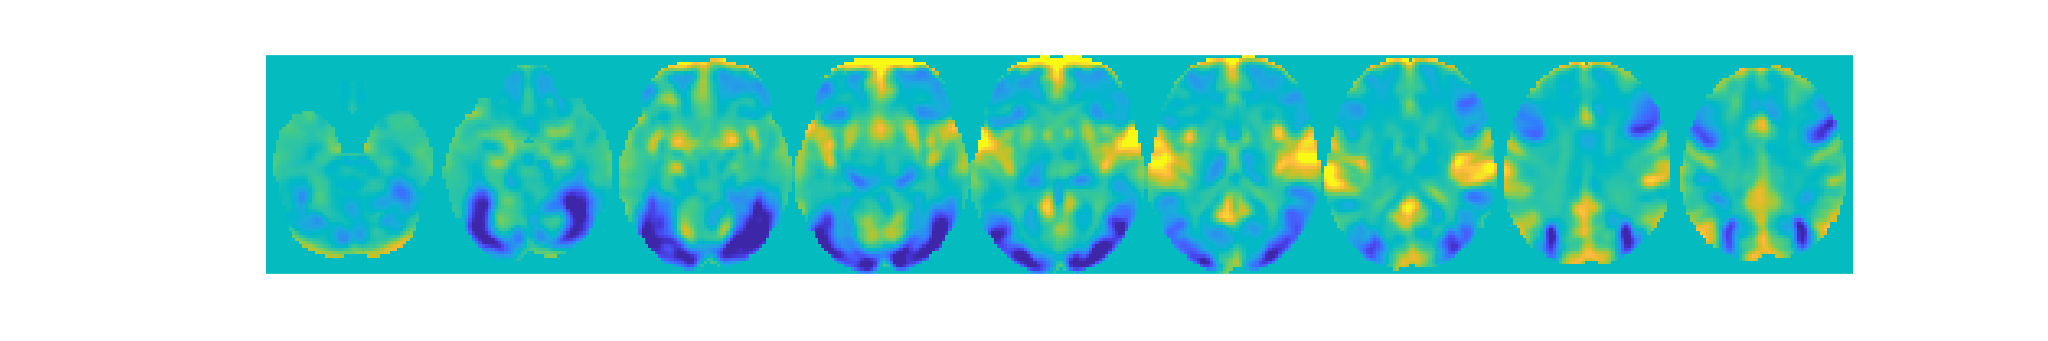

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;


#### Pain > VC :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 99


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 4 participants, size is now 95


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0018"    "participants that are outliers:... sub-0043"    "participants that are outliers:... sub-0044"    "participants that are outliers:... sub-0102"



disp(n);

    {'sub-0018'}    {'sub-0043'}    {'sub-0044'}    {'sub-0102'}



#### Pain > VC :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Pain > VC :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


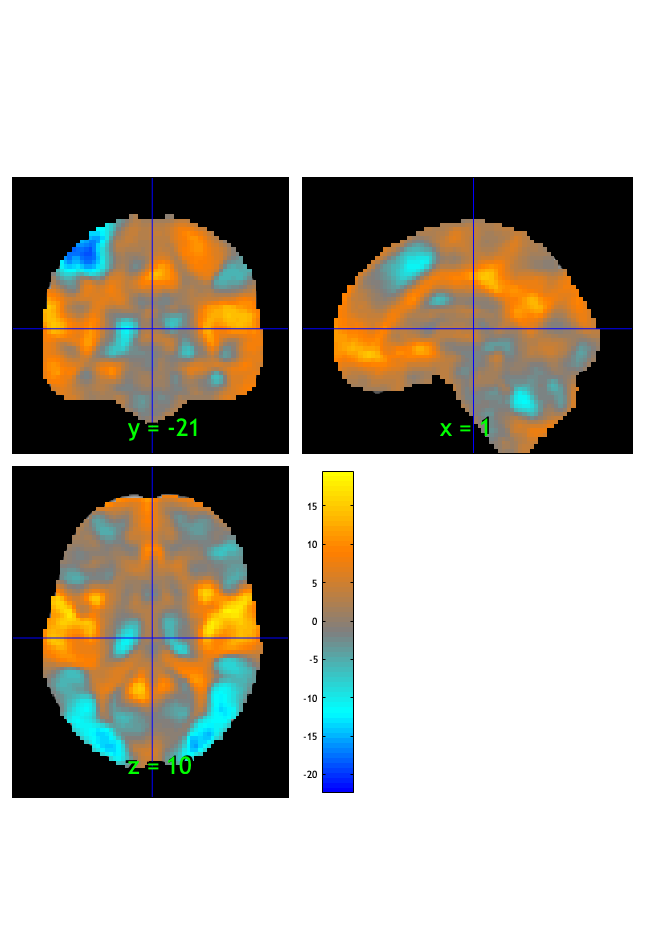

SPM12: spm_check_registration (v7759)              16:45:29 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.034056

Image   1
 20 contig. clusters, sizes   1 to 67918
Positive effect: 39459 voxels, min p-value: 0.00000000
Negative effect: 28541 voxels, min p-value: 0.00000000


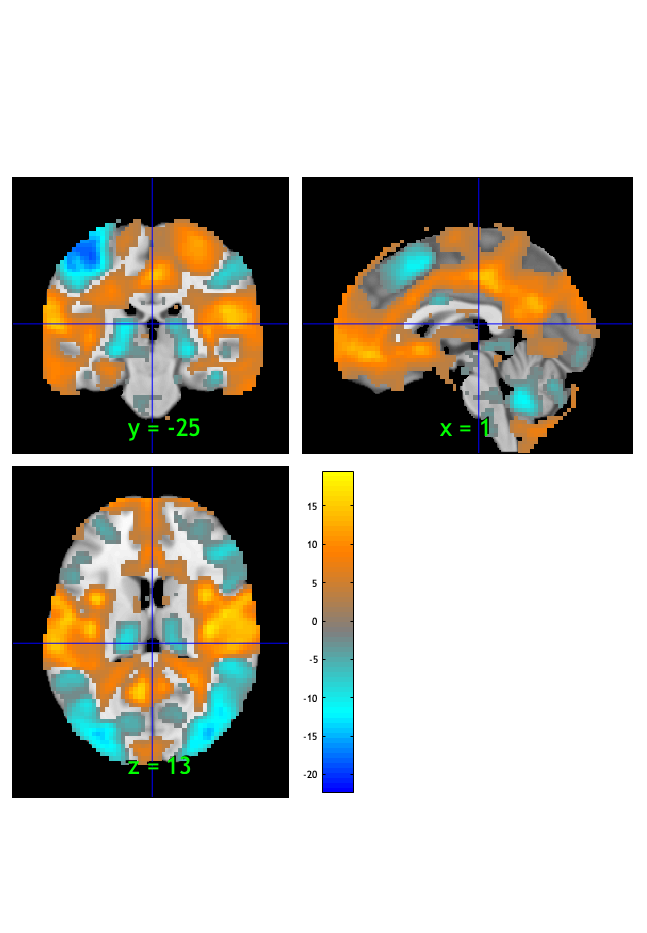

SPM12: spm_check_registration (v7759)              16:45:30 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(fdr_t);

drawnow, snapnow;

fdr_t = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000508

Image   1
 25 contig. clusters, sizes   1 to 50348
Positive effect: 28813 voxels, min p-value: 0.00000000
Negative effect: 21890 voxels, min p-value: 0.00000000


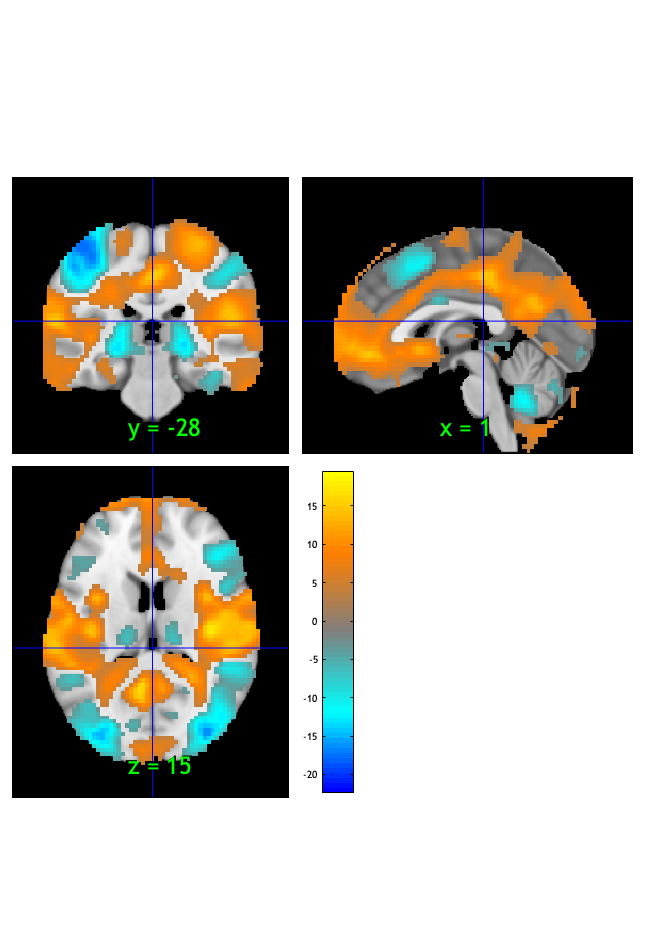

SPM12: spm_check_registration (v7759)              16:45:31 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


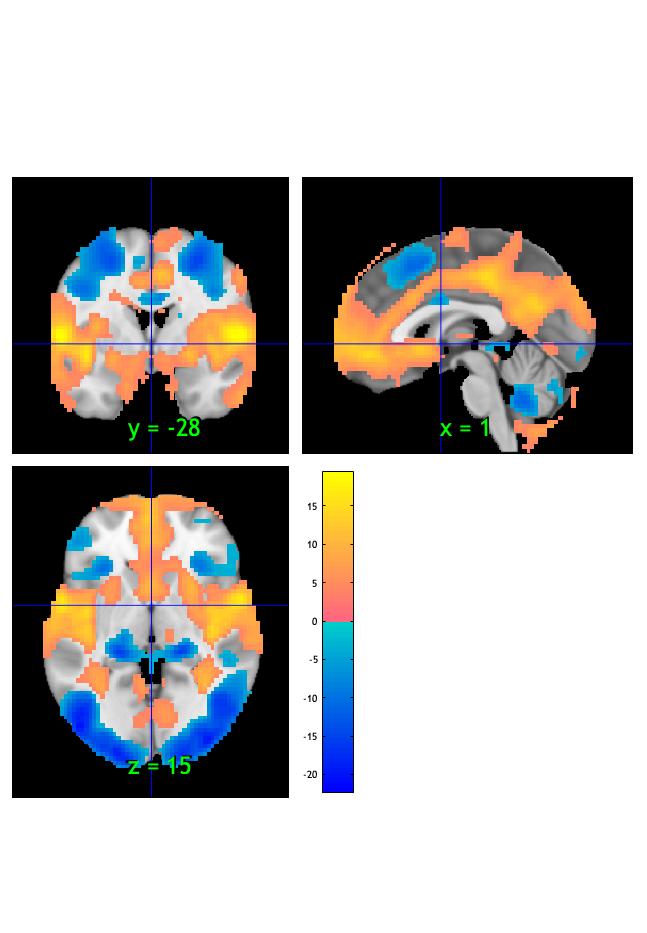

orthviews(fdr_t);

drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

Setting up fmridisplay objects


sagittal montage: 1068 voxels displayed, 49635 not displayed on these slices


sagittal montage: 1094 voxels displayed, 49609 not displayed on these slices


sagittal montage: 1047 voxels displayed, 49656 not displayed on these slices


axial montage: 9511 voxels displayed, 41192 not displayed on these slices


axial montage: 10394 voxels displayed, 40309 not displayed on these slices


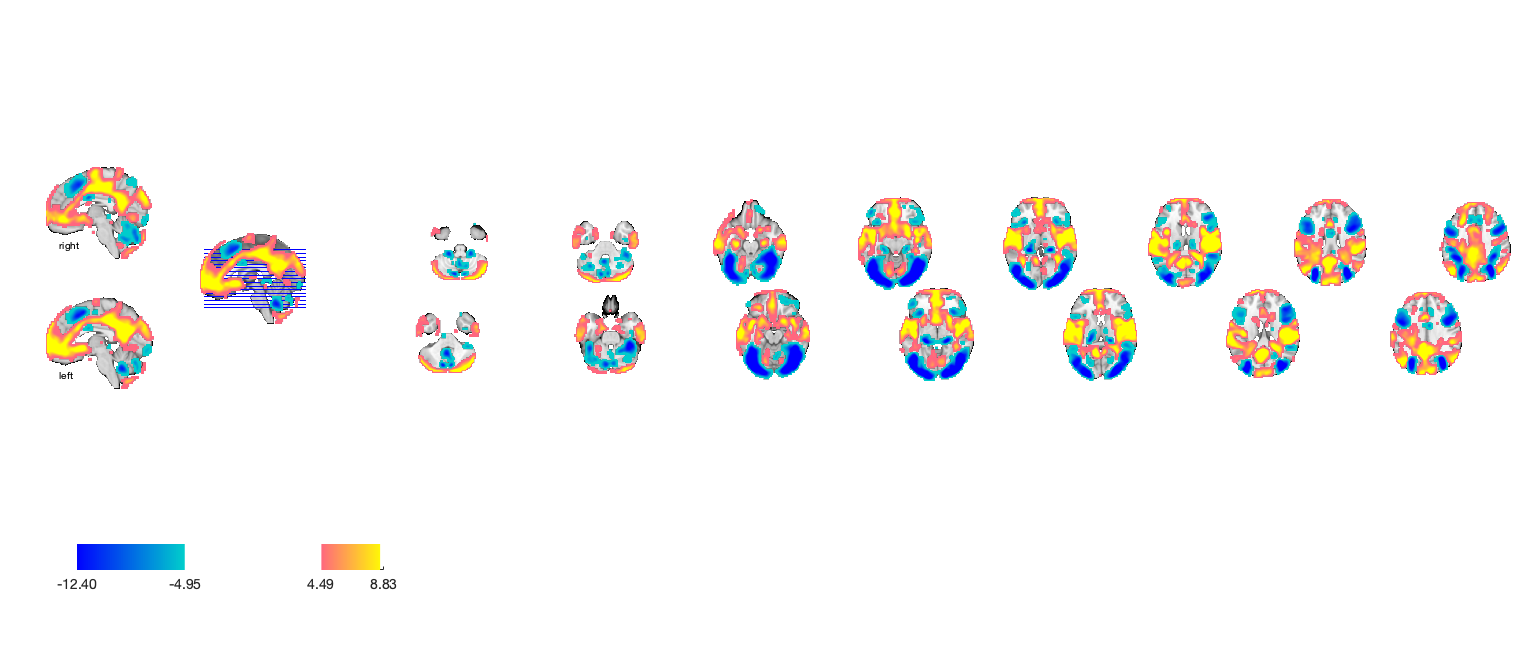

drawnow, snapnow;

#### Pain > VC :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low       words_low        testr_high     words_high  
    _________    ________________    __________    _____________

    -0.52465     {'visual'      }     0.36247      {'rating'   }
    -0.46463     {'object'      }     0.34118      {'sensation'}
    -0.43149     {'objects'     }     0.34025      {'pain'     }
    -0.34862     {'shape'       }     0.31548      {'ratings'  }
    -0.34789     {'attention'   }     0.31184      {'positive' }
    -0.33073     {'letter'      }     0.30252      {'negative' }
    -0.30522     {'perceptual'  }     0.29098      {'anxiety'  }
    -0.29873     {'color'       }     0.28151      {'trait'    }
    -0.29081     {'rotation'    }     0.27237      {'painful'  }
    -0.28689     {'orthographic'}     0.26573

**Pain > VC :: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Can

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(imgs2, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	0.1610	28.8980	0.0000	1.0000	
Cog Wholebrain	-0.0118	-3.8539	0.0002	1.0000	
Emo Wholebrain	-0.1418	-26.6417	0.0000	1.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}      0.16101     0.0054841      29.36    2.2204e-15      3.0123
    {'Cog Wholebrain' }    -0.011786     0.0030572    -3.8551    0.00021159    -0.39552
    {'Emo Wholebrain' }     -0.14183     0.0052638    -26.945    2.2204e-15     -2.7645



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {95×3 cell}
        text_han: {95×3 cell}
       point_han: {95×3 cell}
    star_handles: [9.0001 10.0001 11.0001]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(imgs2, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 
Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}      0.15579      0.005631     27.666    2.2204e-15      2.8385
    {'Cog Wholebrain' }    -0.012373     0.0029583    -4.1825    6.4718e-05    -0.42912
    {'Emo Wholebrain' }     -0.13788     0.0053476    -25.784    2.2204e-15     -2.6454



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {95×3 cell}
        text_han: {95×3 cell}
       point_han: {95×3 cell}
    star_handles: [12.0001 13.0001 14.0001]


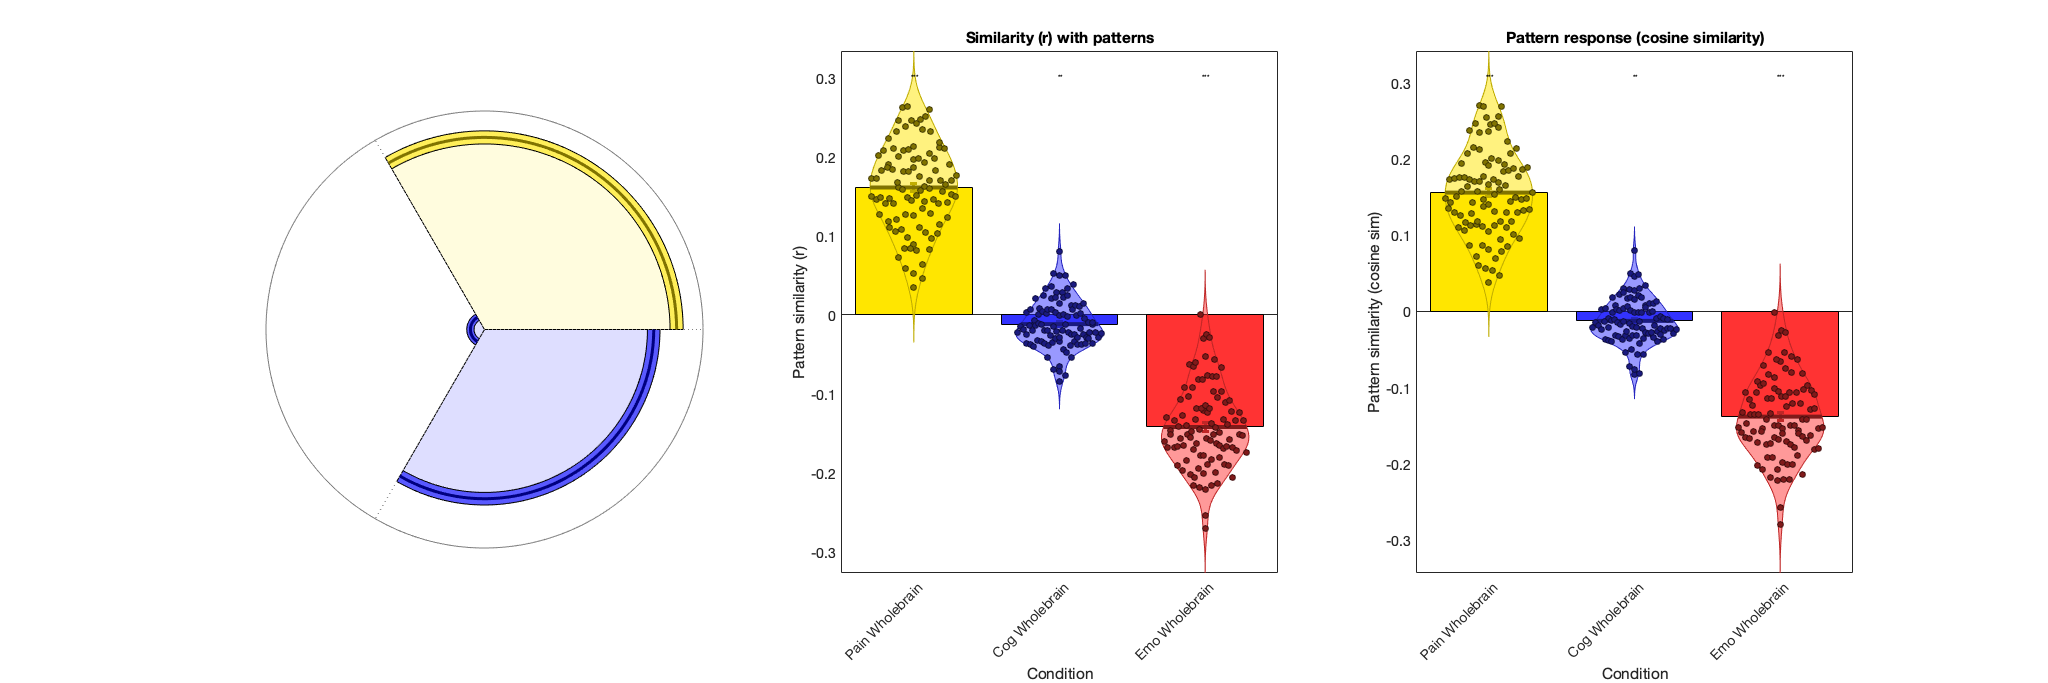

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

## Vicarious > (Pain & Cognitive)

#### Vicarious > PC :: load dataset

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_CESO/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0006.nii'));
spm('Defaults','fMRI'); 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii


sampleto = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_CESO/1stLevel/sub-0013/con_0006.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 39535452 bytes
Loading image number:    99
Elapsed time is 17.147300 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 9377161  Bit rate: 23.16 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C'};

#### Vicarious > PC :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

SPM12: spm_check_registration (v7759)              17:41:14 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


#### Vicarious > PC :: Plot diagnostics, before l2norm

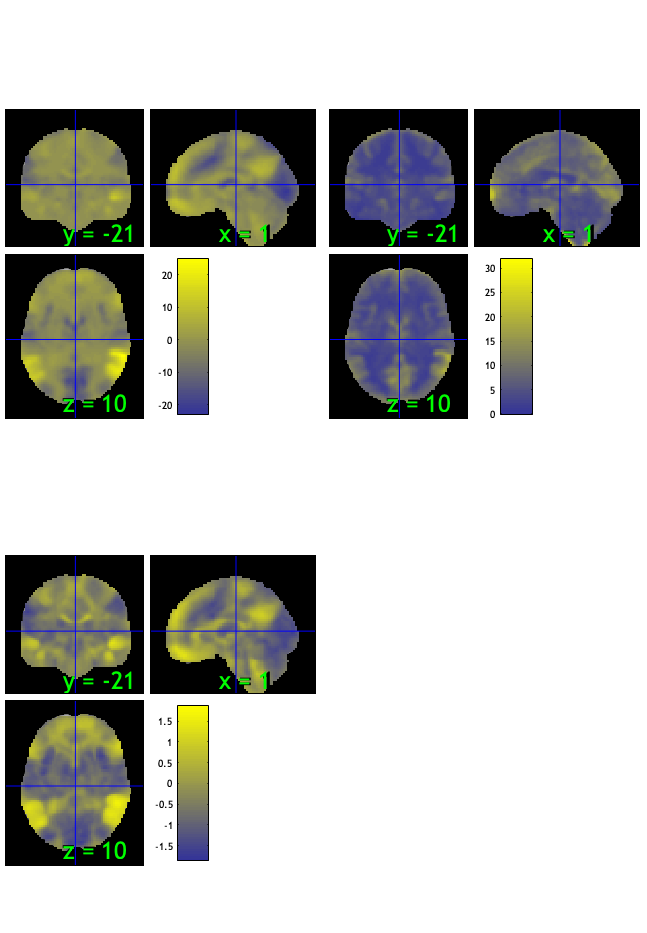

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 37.37%
Expected 4.95 outside 95% ellipsoid, found   3

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 26 
Uncorrected: 3 images		Cases 26 27 79 

Retained 6 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 44.44%
Expected 4.95 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 7 images		Cases 6 13 26 35 56 62 70 

Mahalanobis (cov and corr, q<0.05 corrected):
  1 images 
                               Outlier_count    Percentage
                               <s

SPM12: spm_check_registration (v7759)              17:41:45 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

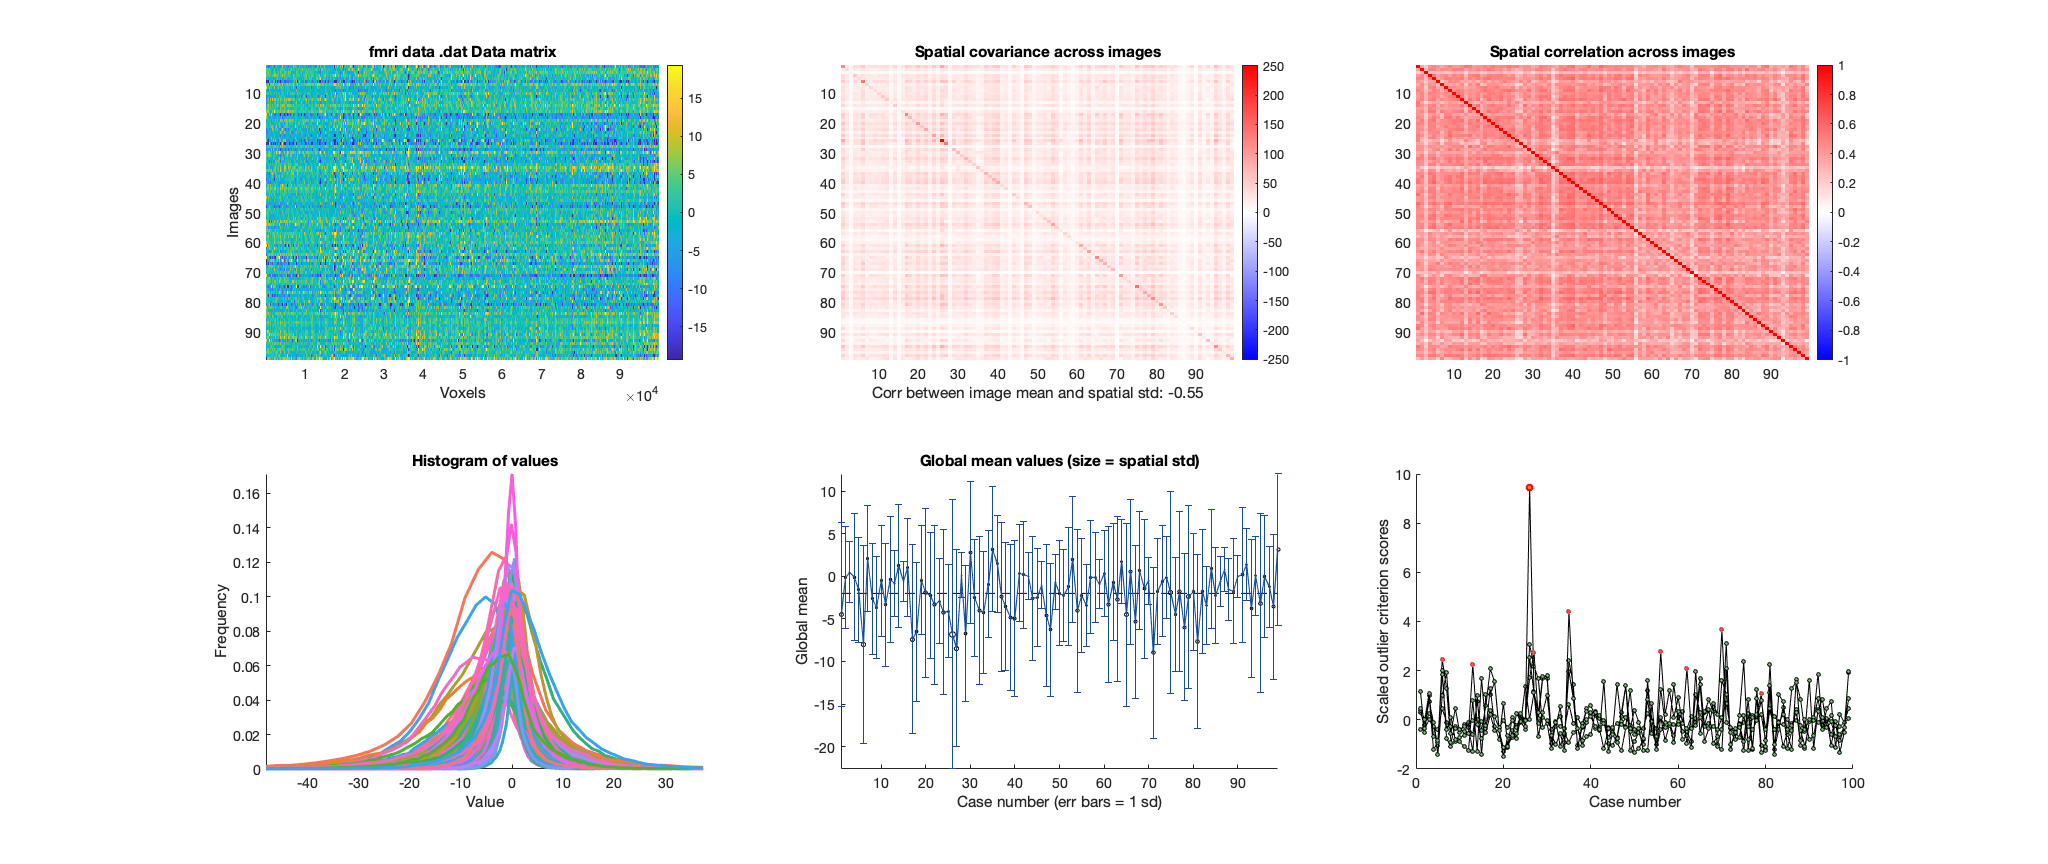

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


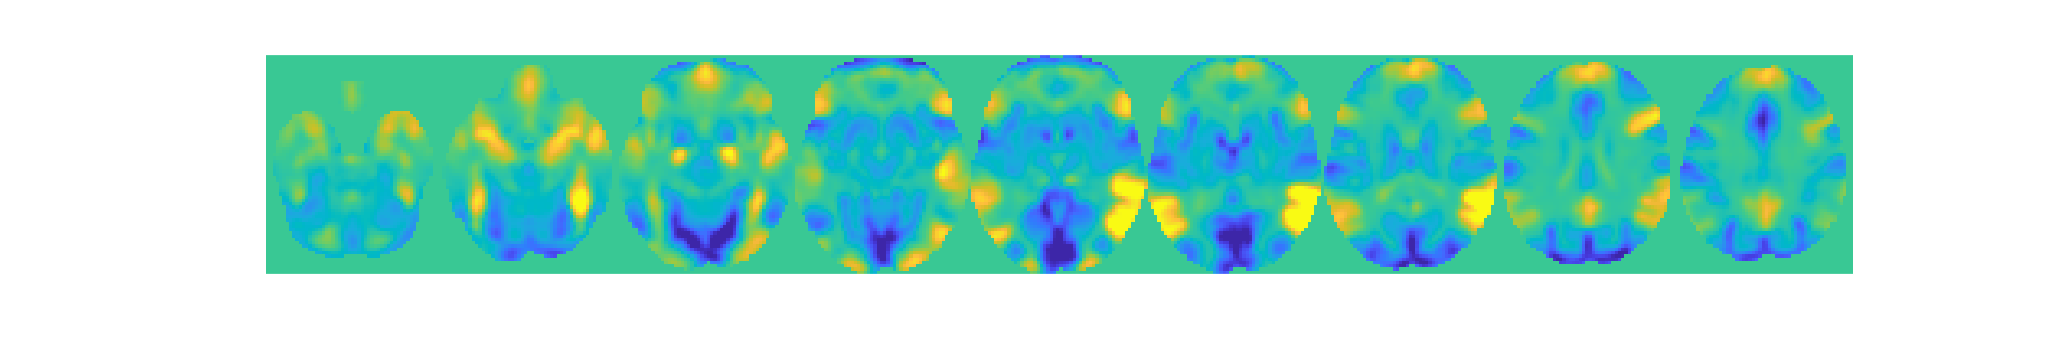

drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Vicarious > PC :: run robfit

set(gcf,'Visible','on');
figure ('Visible', 'on');
drawnow, snapnow;

#### Vicarious > PC :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 99


%for s = 1:length(wh_outlier_corr)
  %  disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 1 participants, size is now 98


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

participants that are outliers:... sub-0043


disp(n);

sub-0043


#### Vicarious > PC :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Vicarious > PC :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


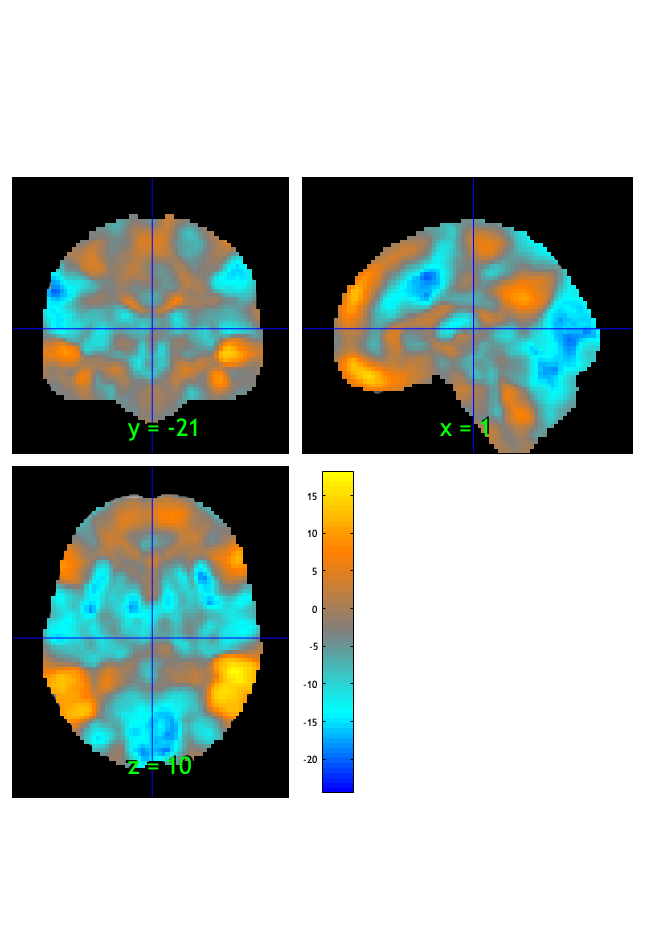

SPM12: spm_check_registration (v7759)              17:41:51 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.039036

Image   1
  9 contig. clusters, sizes   1 to 77951
Positive effect: 20678 voxels, min p-value: 0.00000000
Negative effect: 57300 voxels, min p-value: 0.00000000


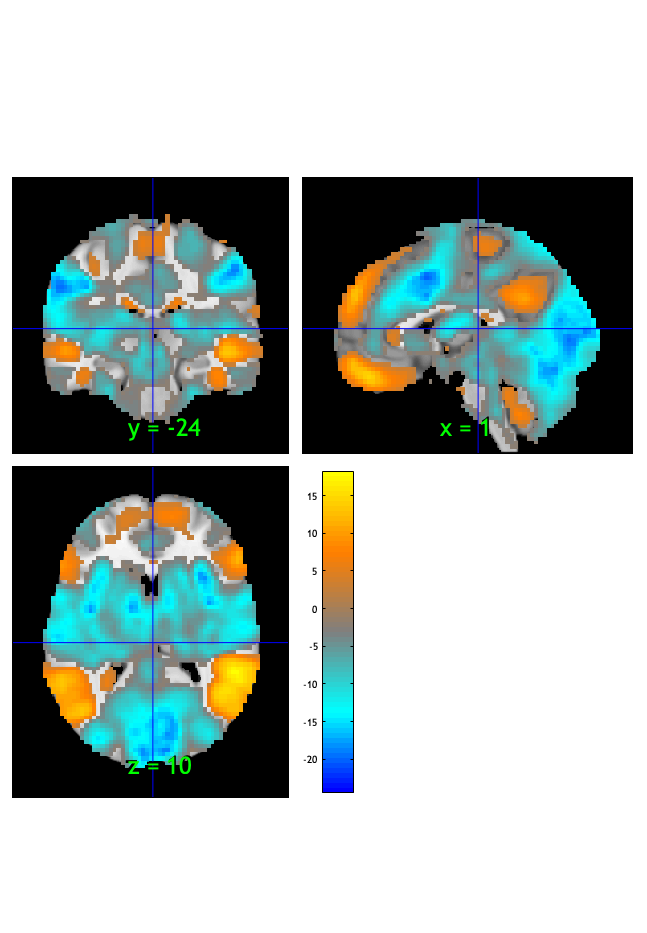

SPM12: spm_check_registration (v7759)              17:41:53 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(fdr_t);

drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

Setting up fmridisplay objects


sagittal montage: 1971 voxels displayed, 76007 not displayed on these slices


sagittal montage: 2024 voxels displayed, 75954 not displayed on these slices


sagittal montage: 1933 voxels displayed, 76045 not displayed on these slices


axial montage: 14565 voxels displayed, 63413 not displayed on these slices


axial montage: 15668 voxels displayed, 62310 not displayed on these slices


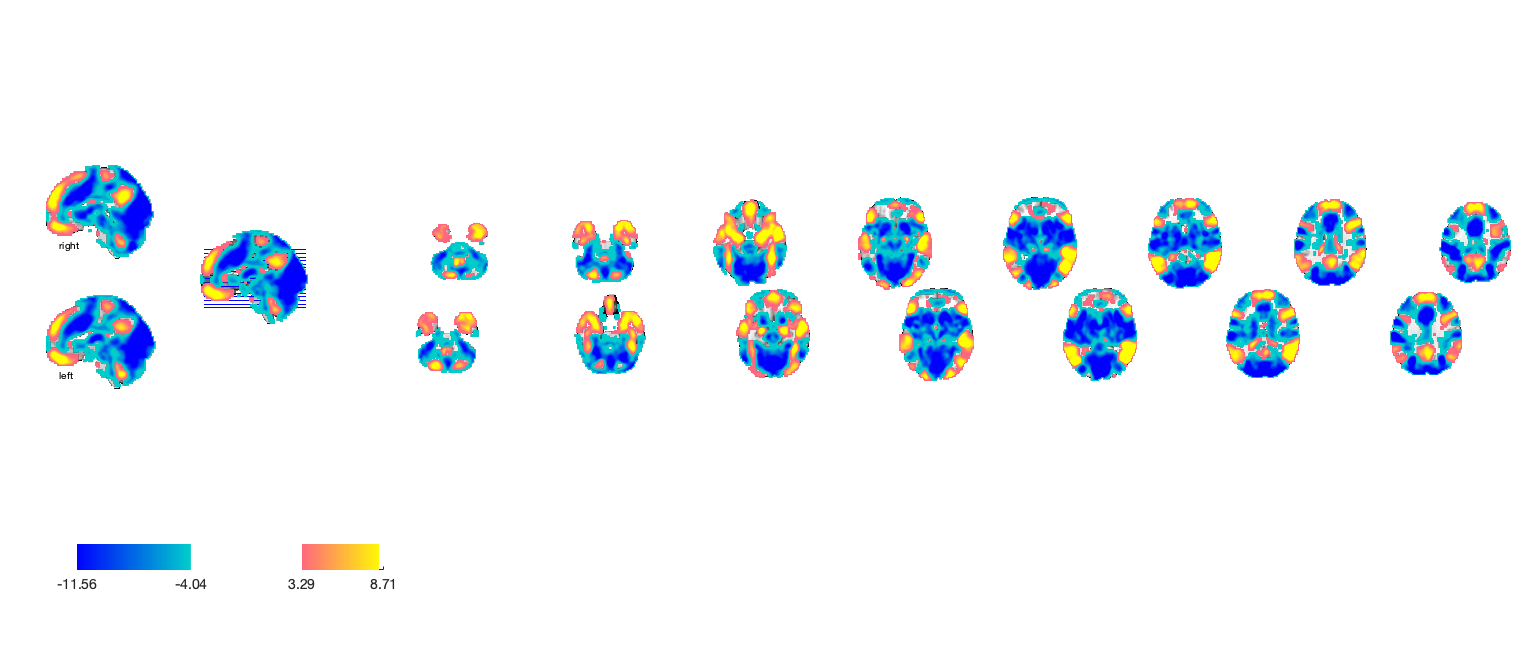

drawnow, snapnow;

#### Vicarious > PC :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low        words_low        testr_high      words_high   
    _________    _________________    __________    _______________

    -0.24204     {'motor'        }     0.36409      {'social'     }
    -0.22962     {'spatial'      }     0.30776      {'face'       }
    -0.20779     {'imagery'      }     0.30155      {'emotion'    }
    -0.20604     {'finger'       }     0.28793      {'facial'     }
    -0.19751     {'tactile'      }     0.28714      {'faces'      }
    -0.19716     {'execution'    }     0.28322      {'expression' }
    -0.19147     {'somatosensory'}     0.26992      {'expressions'}
    -0.18804     {'sensorimotor' }     0.25906      {'person'     }
    -0.18534     {'eye'          }     0.25482      {'story'      }
    -0.18293

Vicarious > PC **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Can

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(imgs2, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.1401	-26.1970	0.0000	1.0000	
Cog Wholebrain	0.0173	5.9228	0.0000	1.0000	
Emo Wholebrain	0.1171	22.3240	0.0000	1.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}     -0.14014     0.0052757    -26.563    2.2204e-15    -2.6833 
    {'Cog Wholebrain' }     0.017331     0.0029259     5.9233    4.7949e-08    0.59835 
    {'Emo Wholebrain' }      0.11712      0.005208     22.489    2.2204e-15     2.2718 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {98×3 cell}
        text_han: {98×3 cell}
       point_han: {98×3 cell}
    star_handles: [9.0004 10.0004 11.0004]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(imgs2, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 
Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error      T           P         Cohens_d
    ___________________    __________    _________    ______    __________    ________

    {'Pain Wholebrain'}     -0.13611       0.00538     -25.3    2.2204e-15    -2.5557 
    {'Cog Wholebrain' }     0.015667     0.0027803    5.6353    1.7122e-07    0.56925 
    {'Emo Wholebrain' }        0.116     0.0052411    22.133    2.2204e-15     2.2358 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {98×3 cell}
        text_han: {98×3 cell}
       point_han: {98×3 cell}
    star_handles: [12.0004 13.0004 14.0004]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

## Cognitive > (Pain & Vicarious)

#### Cognitive > PV :: load dataset

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_CESO/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0007.nii'));
spm('Defaults','fMRI');
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii


sampleto = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_CESO/1stLevel/sub-0013/con_0007.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 39535452 bytes
Loading image number:    99
Elapsed time is 17.159734 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 9413473  Bit rate: 23.17 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C'};

#### Cognitive > PV :: `check data coverage`

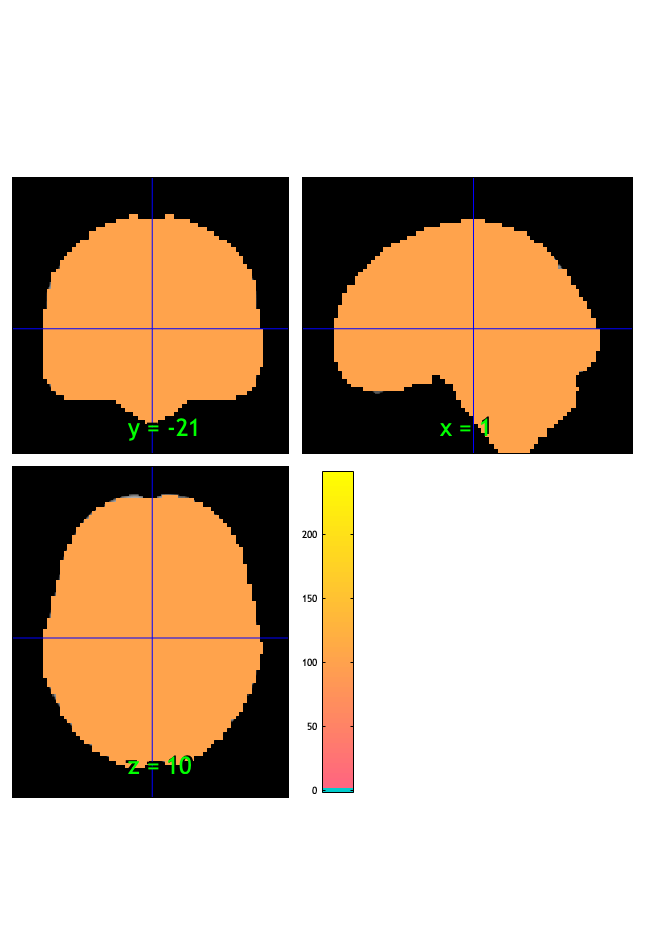

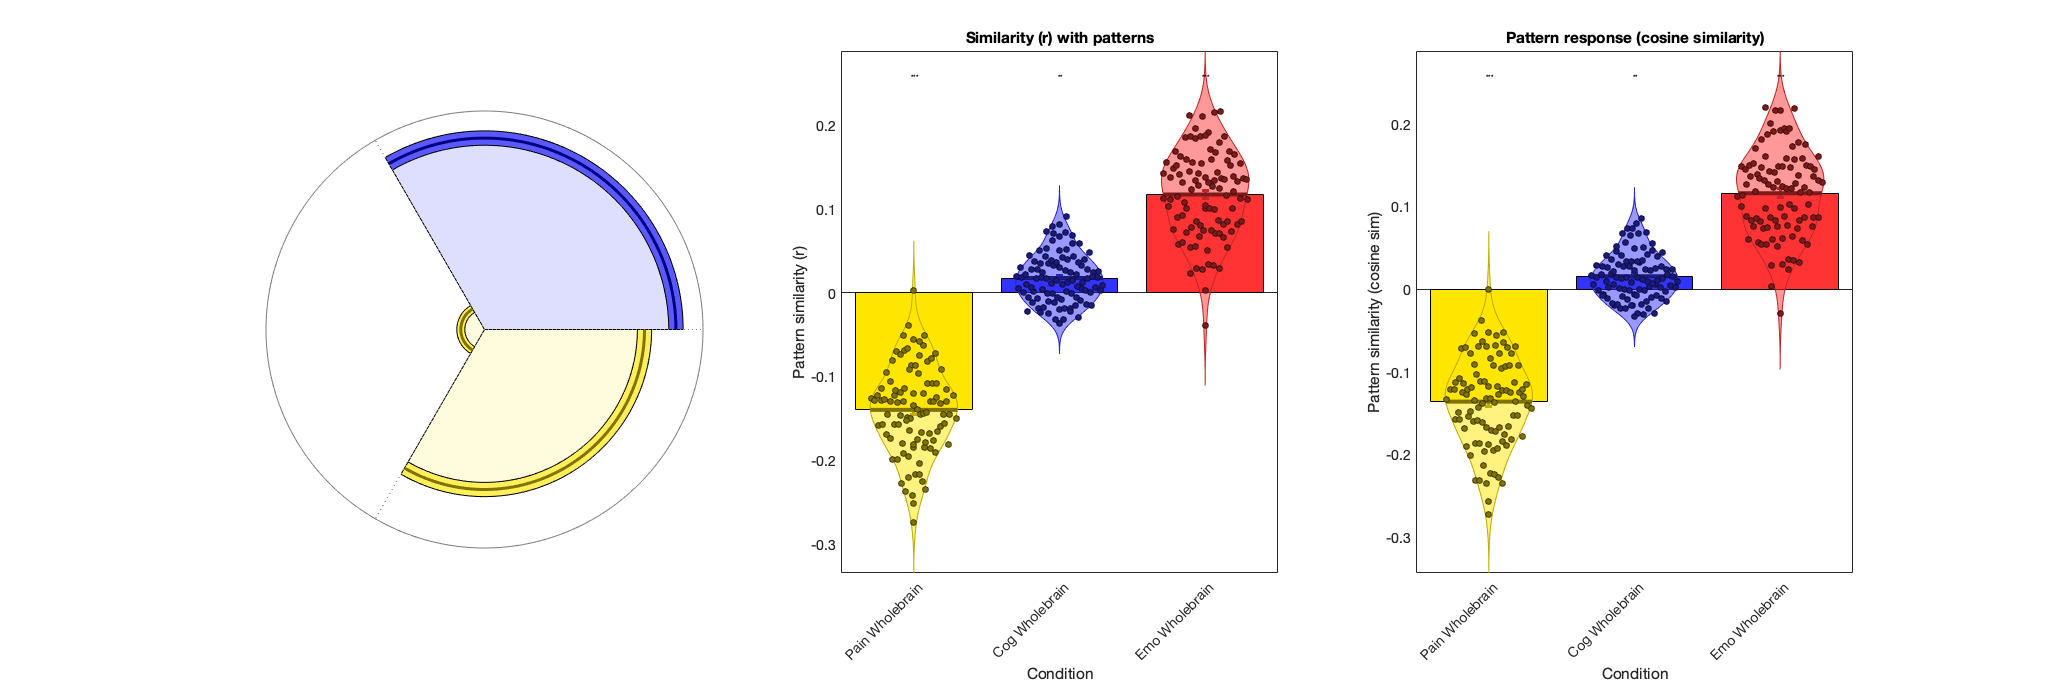

SPM12: spm_check_registration (v7759)              17:42:53 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

#### Cognitive > PV :: Plot diagnostics, before l2norm

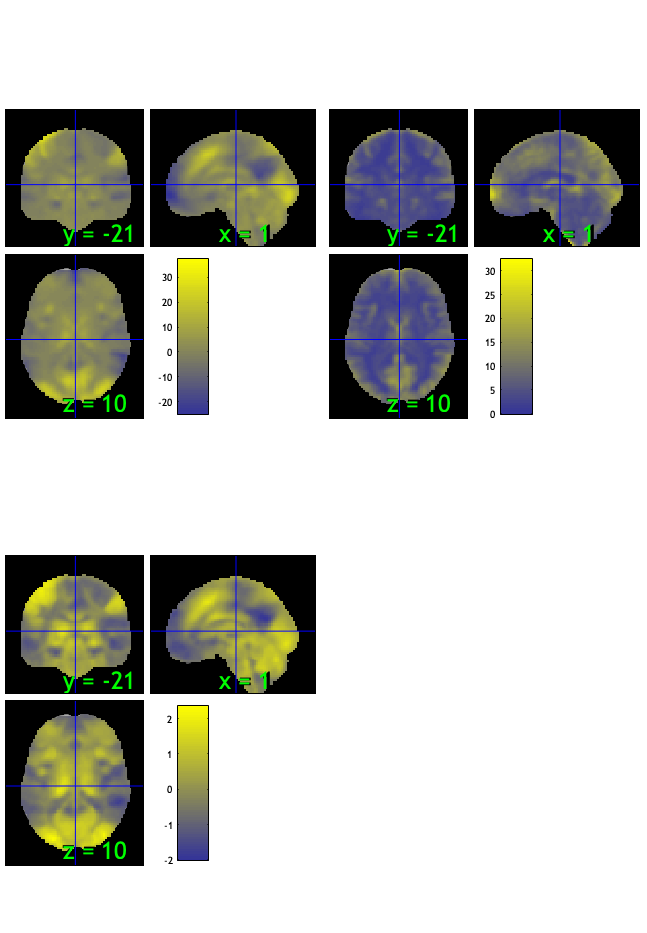

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 4 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 34.34%
Expected 4.95 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 26 
Uncorrected: 7 images		Cases 6 26 27 37 61 63 99 

Retained 6 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 45.45%
Expected 4.95 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 26 
Uncorrected: 7 images		Cases 13 26 27 41 68 75 83 

Mahalanobis (cov and corr, q<0.05 corrected):
  1 images 
                               Outlier_count    Percentage
                   

SPM12: spm_check_registration (v7759)              17:43:29 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

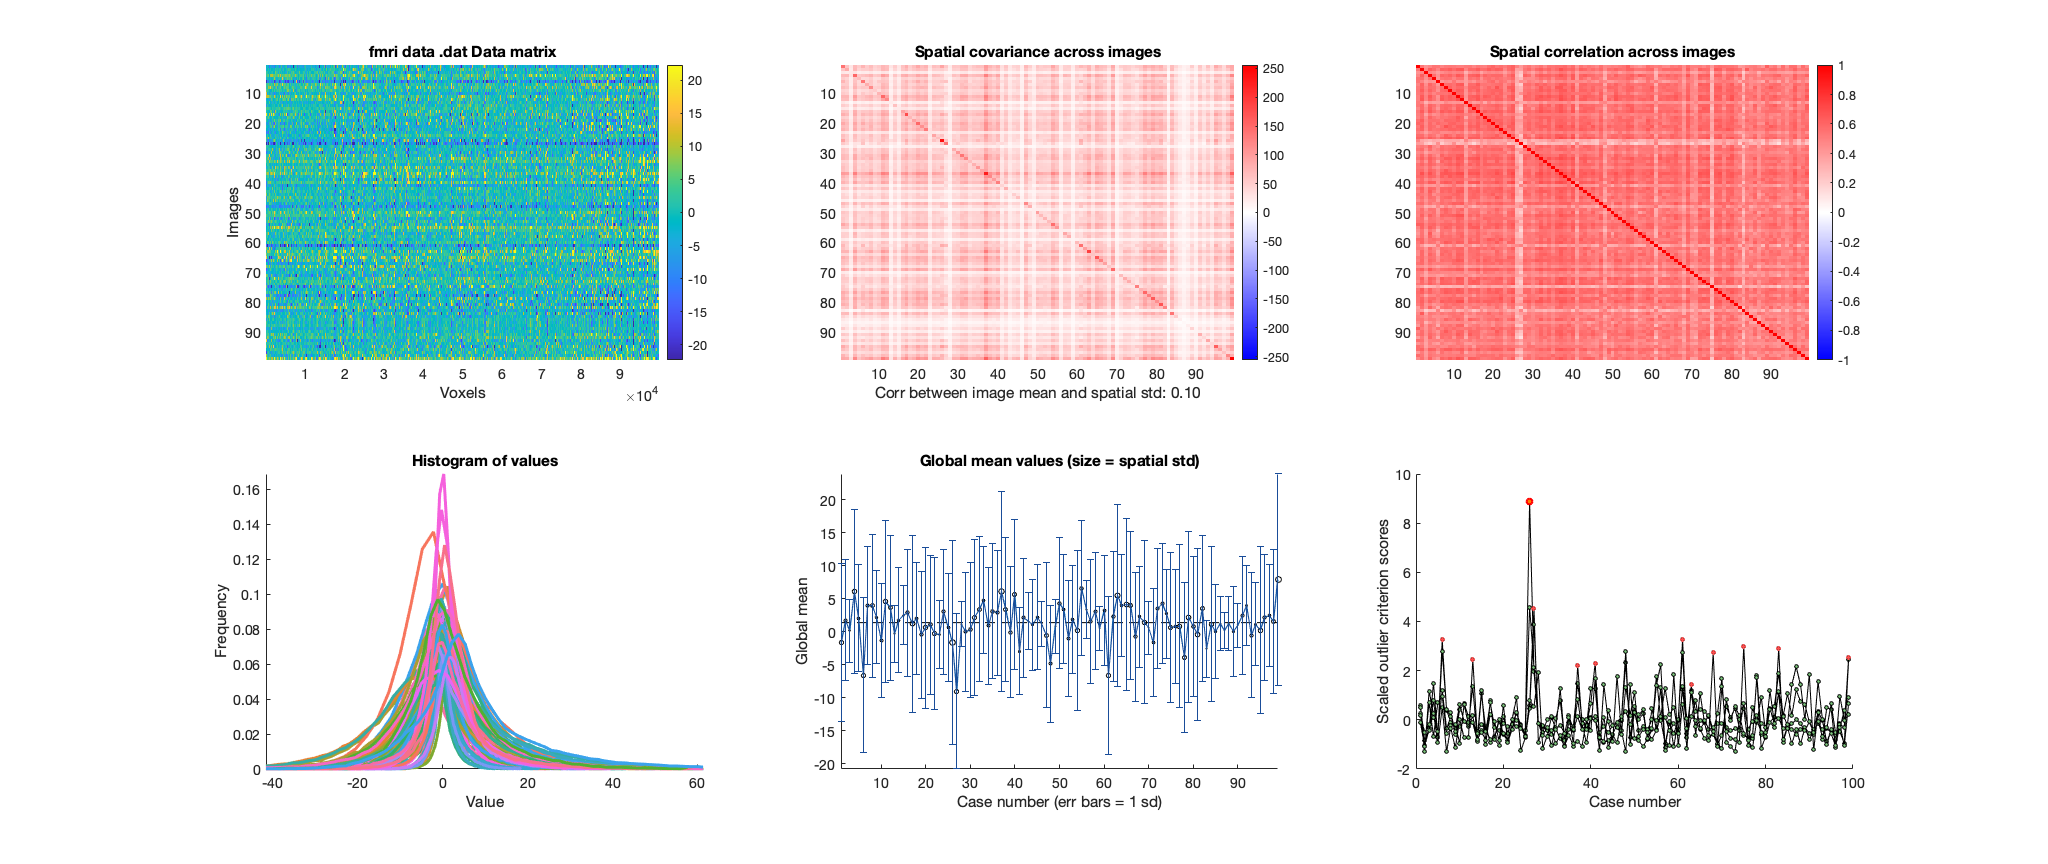

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


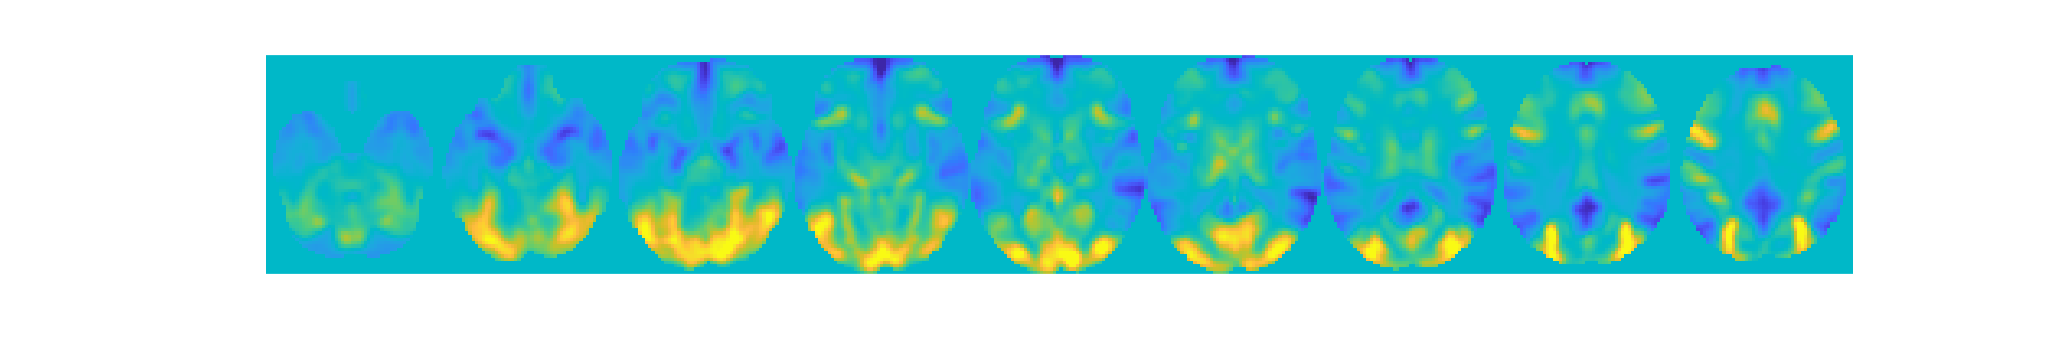

drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Cognitive > PV :: run robfit

set(gcf,'Visible','on');
figure ('Visible', 'on');
drawnow, snapnow;

#### Cognitive > PV :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 99


%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 1 participants, size is now 98


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

participants that are outliers:... sub-0043


disp(n);

sub-0043


#### Cognitive > PV:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Cognitive > PV :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


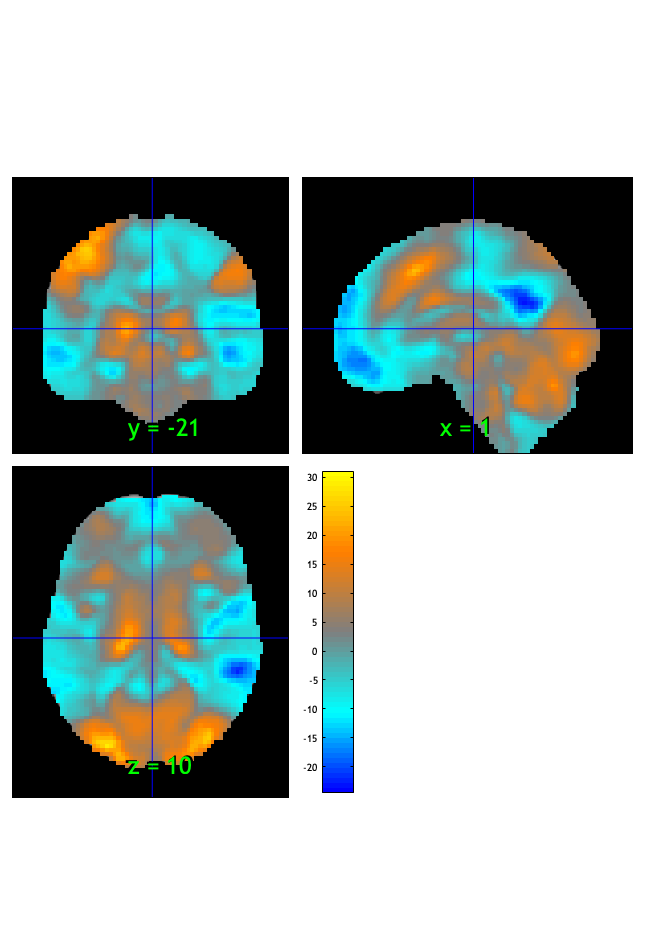

SPM12: spm_check_registration (v7759)              17:43:34 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.040001

Image   1
 10 contig. clusters, sizes   1 to 79902
Positive effect: 43968 voxels, min p-value: 0.00000000
Negative effect: 35947 voxels, min p-value: 0.00000000


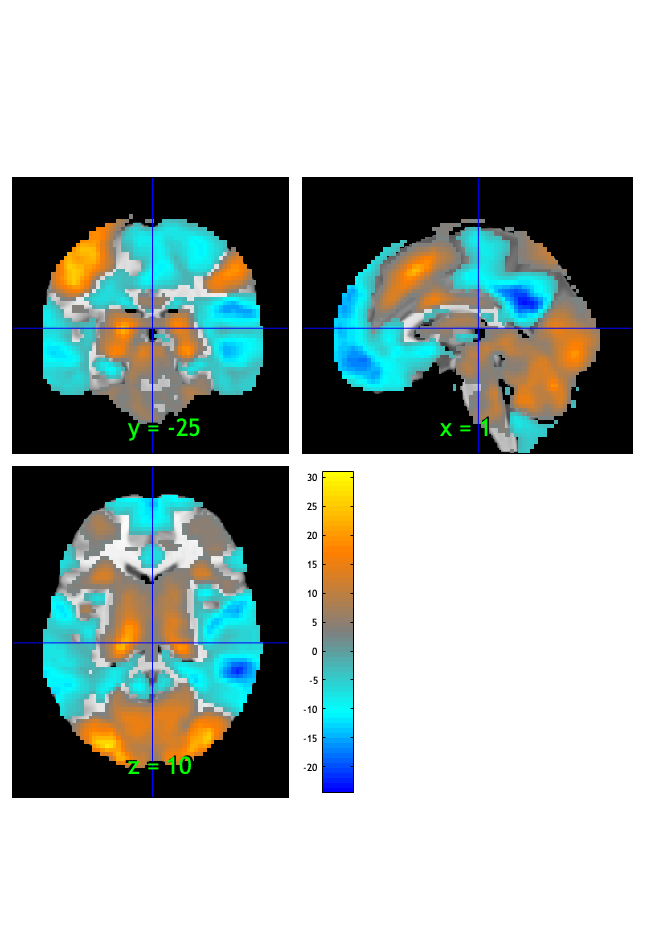

SPM12: spm_check_registration (v7759)              17:43:35 - 12/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


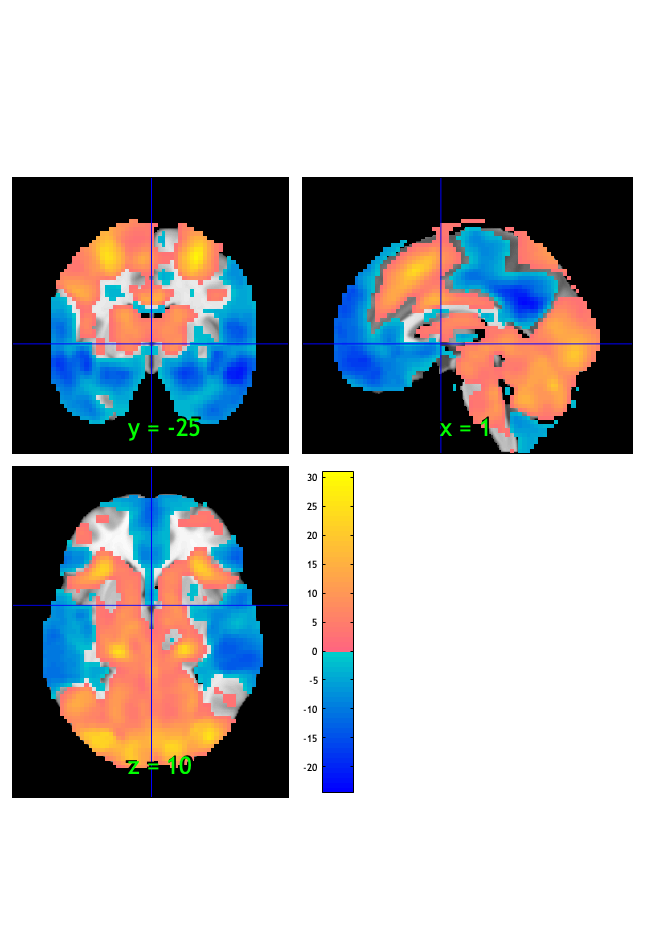

orthviews(fdr_t);

drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

Setting up fmridisplay objects


sagittal montage: 2039 voxels displayed, 77876 not displayed on these slices


sagittal montage: 1978 voxels displayed, 77937 not displayed on these slices


sagittal montage: 1983 voxels displayed, 77932 not displayed on these slices


axial montage: 14978 voxels displayed, 64937 not displayed on these slices


axial montage: 16350 voxels displayed, 63565 not displayed on these slices


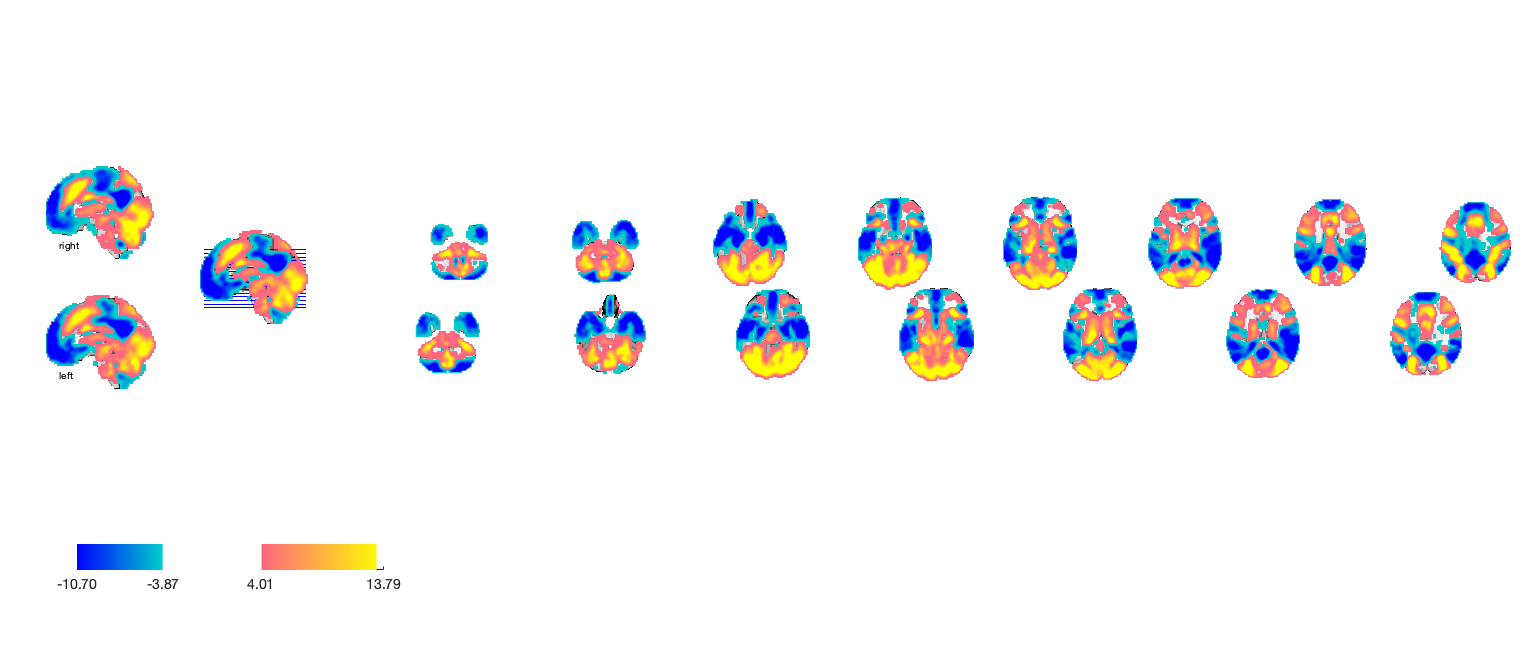

drawnow, snapnow;

#### Cognitive > PV :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low      words_low      testr_high       words_high   
    _________    _____________    __________    ________________

    -0.34988     {'rating'   }     0.47063      {'visual'      }
    -0.32866     {'trait'    }     0.34914      {'shape'       }
    -0.32835     {'social'   }     0.33765      {'object'      }
     -0.3271     {'emotion'  }     0.33052      {'attention'   }
    -0.32161     {'affect'   }     0.32404      {'eye'         }
    -0.31639     {'person'   }     0.31858      {'letter'      }
    -0.30788     {'negative' }     0.31375      {'visuospatial'}
    -0.30525     {'positive' }     0.30483      {'spatial'     }
     -0.3037     {'affective'}      0.3042      {'color'       }
    -0.30052     {'ratings'  }     0.30405   

Cognitive > PV **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Can

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(imgs2, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0445	-12.9986	0.0000	1.0000	
Cog Wholebrain	0.0006	0.2027	0.8398	0.0000	
Emo Wholebrain	0.0416	11.9365	0.0000	1.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}     -0.044452    0.0034145    -13.019    2.2204e-15     -1.3151
    {'Cog Wholebrain' }    0.00055217    0.0027213    0.20291       0.83963    0.020497
    {'Emo Wholebrain' }      0.041572    0.0034793     11.948    2.2204e-15       1.207



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {98×3 cell}
        text_han: {98×3 cell}
       point_han: {98×3 cell}
    star_handles: [9.0005 10.0005 11.0005]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(imgs2, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 
Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.043637      0.003392    -12.865    2.2204e-15     -1.2995
    {'Cog Wholebrain' }    0.0025263     0.0026243    0.96267       0.33811    0.097244
    {'Emo Wholebrain' }     0.039486     0.0034385     11.484    2.2204e-15        1.16



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {98×3 cell}
        text_han: {98×3 cell}
       point_han: {98×3 cell}
    star_handles: [12.0005 13.0005 14.0005]


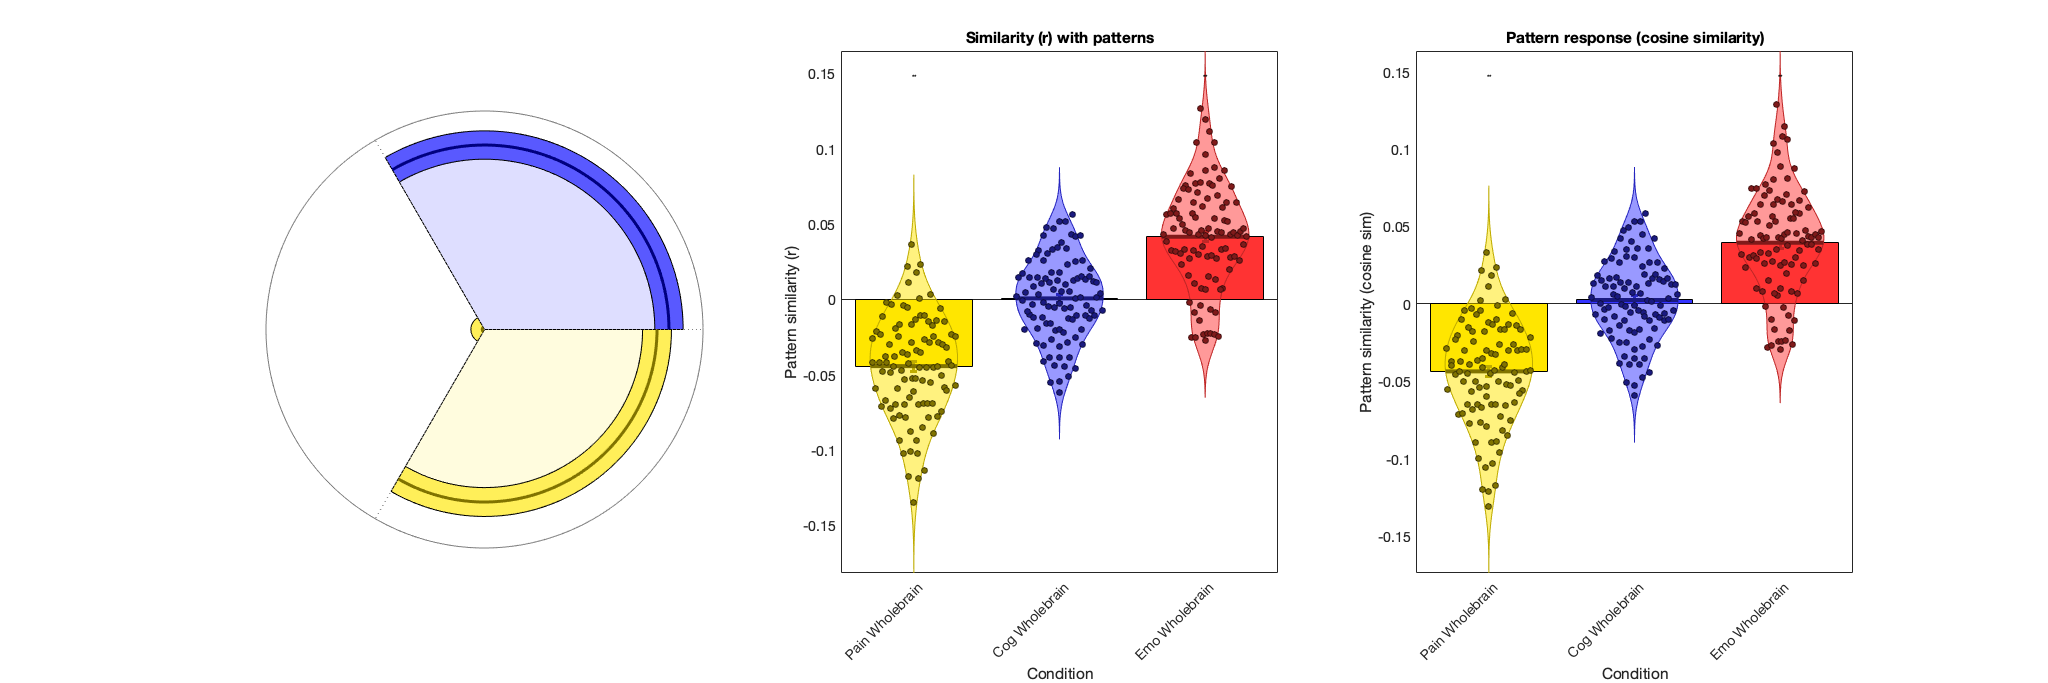

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')
drawnow, snapnow;

% save html
pubdir = pwd;
pubfilename = 's03_PVC_stim_contrasts_ROI.mlx';

p = struct('useNewFigure', false, 'maxHeight', 800, 'maxWidth', 800, ...
  'format', 'html', 'outputDir', pubdir, ...
  'showCode', true, 'stylesheet', which('mxdom2simplehtml_CANlab.xsl'));
htmlfile = publish(pubfilename, p);